# Proof of concept

## Introduction

This file will guide you through the processing of the data, the segmentation and the registration of the embryos to the final heatmap. It will give you an inside of the written code routines and algorithms. Every step will be verified with an example.

## Given data

In this section we will introduce you to the data and the methods of segmentations we are working with. At first we will take a look at the data we are working with.

% Load the data
data = load_data('E:\Embryo_Registration\data\tilting_experiments');

We are provided with three different image channels. The Dapi, GFP and mCherry channel. They are 3D datasets. We will work on the GFP to get a good segmentation of the embryo shape and the mCherry to find and segment the interesting cells, we will visualize in a heatmap in the end. 

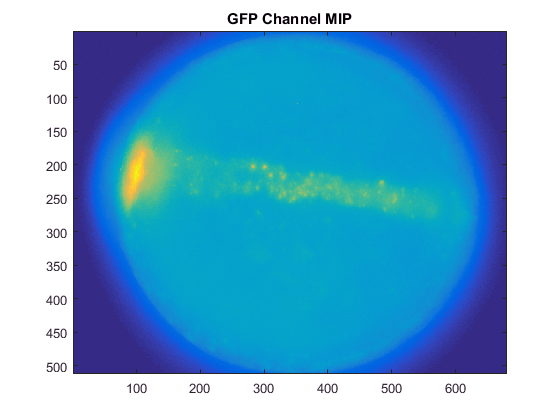

% Visualize one data set with a maximum intensity projection
dataset = data.Data_1;
figure, imagesc(max(dataset.GFP,[],3)),title('GFP Channel MIP');

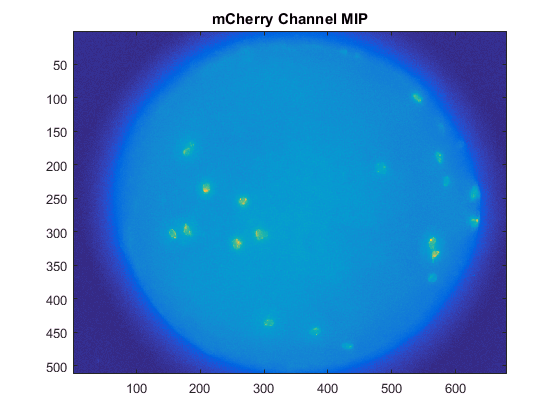

figure, imagesc(max(dataset.mCherry,[],3)),title('mCherry Channel MIP');

As you can see in the images, the shape of the embryo egg is pretty good to see and even the head of the embryo on the left side has a high intensity. The body and the tail have a scattered and low intensity which makes it hard for the segmentation to get the whole shape so we need to be careful with evaluating the parameters and methods. In the mCherry image the cells are pretty good to see because of their high intensity. There is still a problem by determining the cell shape when there are multiple cells close to each other. Additionally there can be segmented one cell as two cells, if the intensity inside of the cell is to low or varies to much. This might distored a perfect segmentation but we will come back to that later.

## Segmentation

As mentioned before the background and the intensity in the body of the embryo are pretty close at some point. So the idea we came across is to get rid of a great part of the background so the segmentation will be much more robust.

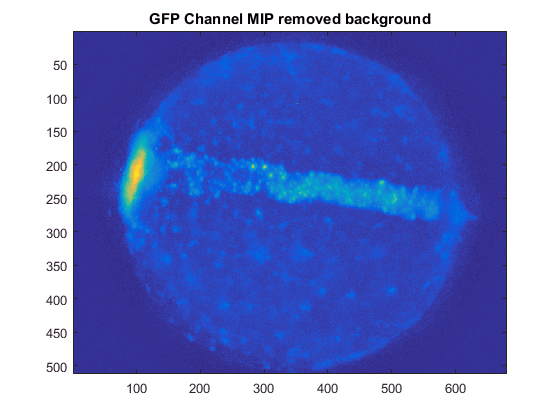

% Remove the background
dataset = removeBackground(dataset);

% Visualization
figure, imagesc(max(dataset.GFP,[],3)),title('GFP Channel MIP removed background');

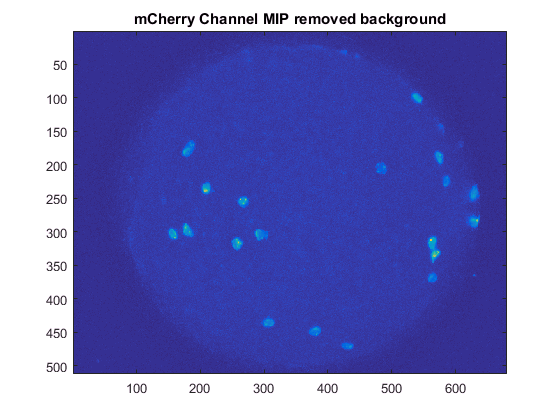

figure, imagesc(max(dataset.mCherry,[],3)),title('mCherry Channel MIP removed background');

Now the contrast of embryo and background is higher. Even the cells are easier to see. 

For the method of segmentation we decided to use a k-means clustering. (reason, advantage, difference to the method before and hyperlink to the paper)

% Scale data
scale = 0.75;
resolution = [1.29/scale, 1.29/scale, 20];
dataset = rescaleSlices(dataset,scale);

% Normalize data
dataset = normalizeData(dataset);

% Segmentation of the embryo in the GFP channel
landmark = segmentGFP(dataset.GFP,round(resolution/scale));

Performing k-means clustering in iteration (0/50)�����1/50)�����2/50)�����3/50)�����4/50)�����5/50)�����6/50)�����7/50)�����8/50)�����9/50)�����10/50)������11/50)������12/50)������13/50)������14/50)������15/50)������16/50)������17/50)������18/50)������19/50)������20/50)������21/50)������22/50)������23/50)������24/50)������25/50)������26/50)������27/50)������28/50)������29/50)������30/50)������31/50)������32/50)������33/50)������34/50)������35/50)������36/50)������37/50)������38/50)������39/50)������40/50)������41/50)������42/50)������43/50)������44/50)������45/50)������46/50)������47/50)������48/50)������49/50)������50/50) ... finished!


% Segmentation of the cells in the mCherry channel
[cells,centCoords] = segmentCells(dataset.mCherry, round(resolution/scale));

Performing k-means clustering in iteration (0/50)�����1/50)�����2/50)�����3/50)�����4/50)�����5/50)�����6/50)�����7/50)�����8/50)�����9/50)�����10/50)������11/50)������12/50)������13/50)������14/50)������15/50)������16/50)������17/50) ... finished!


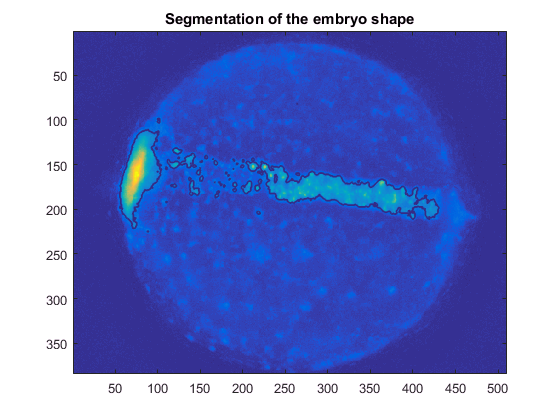

% centCoords contains the coordinates of the cell centroids ins the space.

% Visualization of segmentation
figure,imagesc(max(dataset.GFP,[],3)),hold on,
contour(max(landmark,[],3)),
title('Segmentation of the embryo shape');

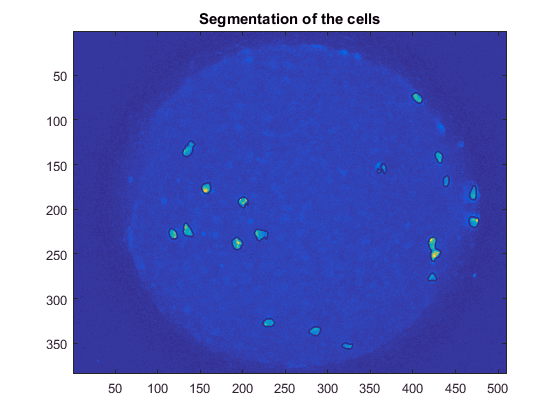

figure,imagesc(max(dataset.mCherry,[],3)),hold on,
contour(max(cells,[],3)),
title('Segmentation of the cells');

## Transforming the data onto a sphere

Now we have the segmentation of the embryo shape and the cells. As one can the shape of the embryo egg is not a perfect ball. It is more like an ellipsoid. Every egg has a different sized and deformed egg shape, so we need to transform the information in one space. We decided that the most natural space would be a perfect ball. In the first step we need to estimate the shape of each embryo egg. Therefore we have an algorithm that will fit an ellipsoid into the 3D images. (Hyperlink and whatever, visualization problem...)

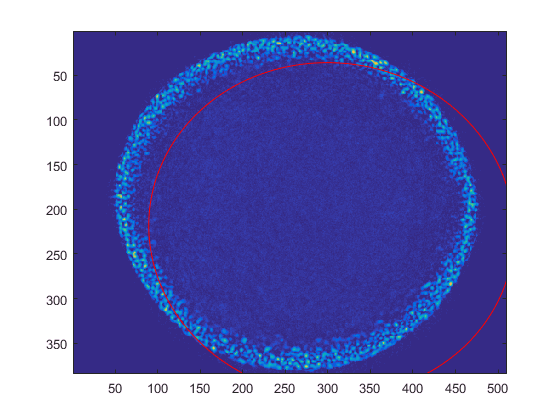

% Estimate surface of embryo by fitting an ellipsoid
[center, radii, axes,v] = estimateEmbryoSurface(dataset.Dapi, [2,2,27]);

% Visualization of one slice and the estimated embryo
Ellipsoid = estimatedEllipsoid(resolution,size(dataset.Dapi),v);
figure, imagesc(dataset.Dapi(:,:,10)), hold on,
contour(Ellipsoid(:,:,10),[1,1],'r');

After estimating the embryo surface we need to transform the coordinates of the cells into the ball. Therefore we will just use standard linear algebra and geometry. This will be provided by the following code.

% Fit coordinates to real resolution
centCoords = diag(round(resolution/scale))*centCoords;

% Transform the coordinates into the sphere. With scaling and rotating.
centCoords(1,:) = centCoords(1,:)-center(1);
centCoords(2,:) = centCoords(2,:)-center(2);
centCoords(3,:) = centCoords(3,:)-center(3);
centCoords = diag([1/radii(1),1/radii(2),1/radii(3)])*axes'*centCoords;

In the next step we want to transform the segmentation onto the sphere. (Insert the description of the current method for the transformation here.) We also need to set a sampling for the sphere. We chose 256 here.

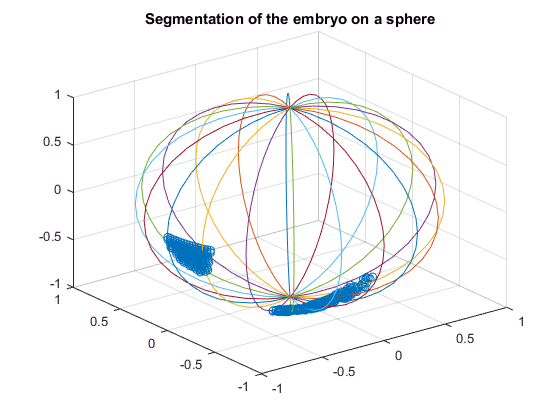

samples = 256;
% Compute the coordinates of the projected segmentation data
regData = compRegData(landmark,samples,resolution,radii,center,axes);

% Visualization of the segmentation data
[x,y,z] = sphere;
figure, scatter3(regData(1,:),regData(2,:),regData(3,:)),
hold on,
plot3(x,y,z),
title('Segmentation of the embryo on a sphere'),
xlim([-1,1]),ylim([-1,1]),zlim([-1,1]);

 Therefore we want to agree that the head of the embryo should always look to the right side of the image. So when it is orientated in the wrong direction we want to rotate it by 180 degrees. In the GUI provided for the researchers there is an interface implemented to check for the direction of the embryo and flip it. But we want to introduce a little method to estimate the orientation of the embryo. Therefore we will look for the highest accumulation of intensity in the horizontal direction of the image and will suggest the side with the highest amount.

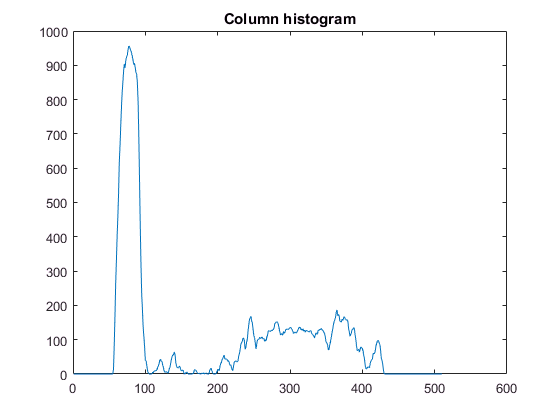

% Generate histogram of column sums
colHistogram = sum(sum(landmark,3),1);
figure,plot(1:size(landmark,2),colHistogram), title('Column histogram');


% Get orientation
headOrientation = determineHeadOrientation(max(landmark,[],3))

headOrientation = left

If the headOrientation is left we need to rotate it to the right. This can be done by just rotation the transformed regData by 180 degrees. This can be done by the build-in function rot90 by:

rot90(regData,2);

## Registration